# Explore the dynamics of a DOUBLE compound **Pendulum**

In this example we're going to derive and then implement the equations of motion for a DOUBLE compound  pendulum. Specifically we're going to:

- Derive the equations of motion using's Lagrange's method

The system that we're going to explore is shown below:

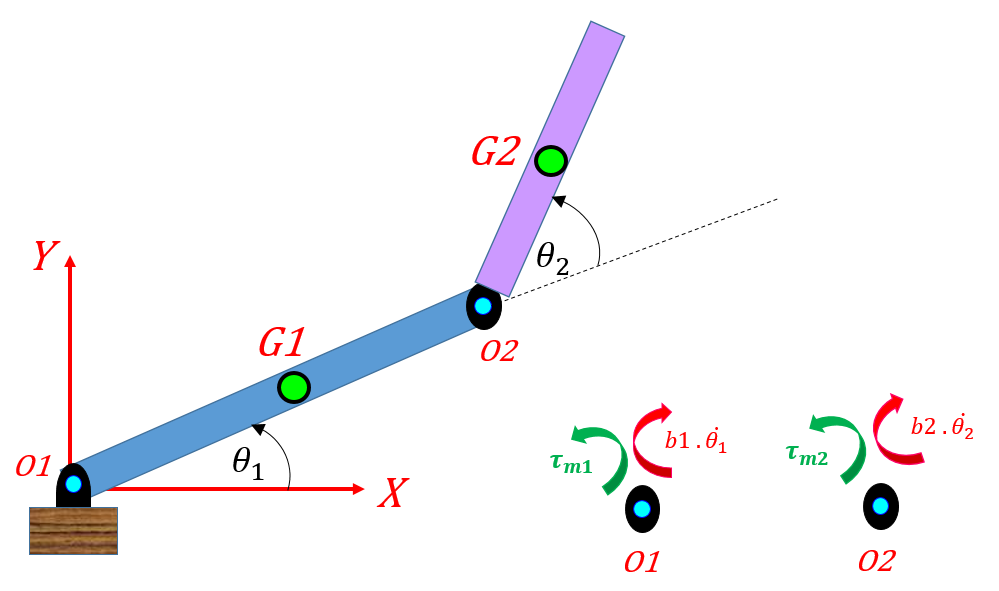

# **STAGE 1:** symbolic derivation of system equations

## Euler-Lagrange equations of motion

                           $\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $     for     $k=1,2, \dots, n$

where  *n* is the DOF of the system, {$q_1, q_2, \dots, q_n$} is a set of generalized coordinates, {$Q_1, Q_2, \dots, Q_n$} is the set of generalized forces associated with those coordinates, and the Lagrangian:  ***L***** =  *****T***  ***-***  ***V****,* is defined as the difference between the kinetic and potential energy of the  *n-* DOF system.

**Note** : 

- For our system, we will choose  *q = {*$\theta_1 \thinspace, \theta_2$*}* 

- This is a 2 degree of freedom system, and as such there are two 2nd order ODEs that can be derived.

## Defining veloctites for the two Links:

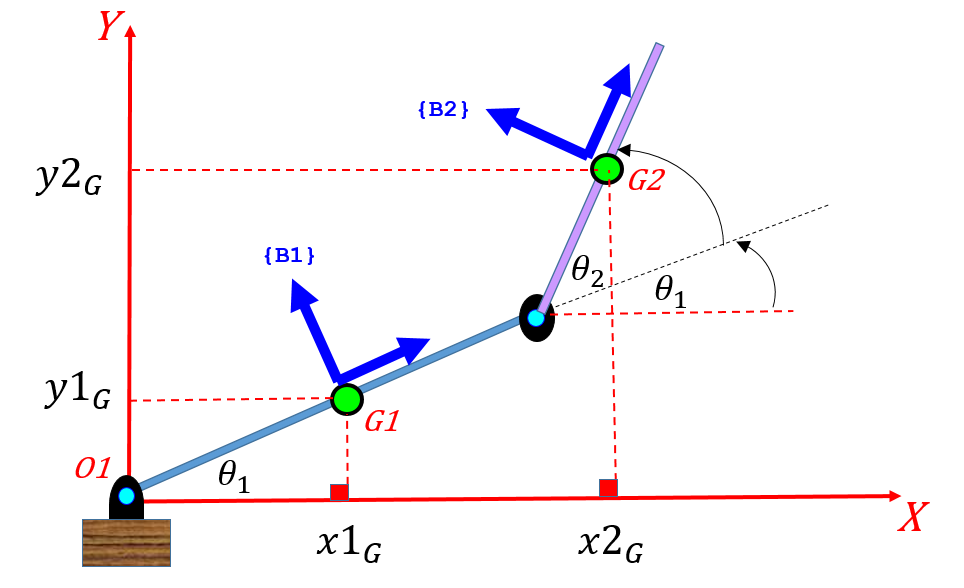

syms m2_s m1_s g_s I1G_s I2G_s
syms L1X_s L2X_s 
syms b1_s  b2_s
syms t theta1(t)  TH1_s  TH1D_s TH1DD_s
syms   theta2(t)  TH2_s  TH2D_s TH2DD_s

Here's ${X}_{1G} \enspace , \enspace
{Y}_{1G} 
$

X1_G        = (L1X_s/2)*cos(theta1(t));
Y1_G        = (L1X_s/2)*sin(theta1(t));

Here's $\dot{X}_{1G} \enspace , \enspace
\ddot{X}_{1G} \enspace , \enspace
\dot{Y}_{1G} \enspace , \enspace
\ddot{Y}_{1G} $

X1_G_d      = diff(X1_G, t); 
X1_G_dd     = diff(X1_G, t, 2); 

Y1_G_d      = diff(Y1_G, t); 
Y1_G_dd     = diff(Y1_G, t, 2); 

Here's ${X}_{2G} \enspace , \enspace
{Y}_{2G} 
$

alpha       = theta1(t) + theta2(t);
X2_G        = L1X_s*cos(theta1(t)) + (L2X_s/2)*cos(alpha);
Y2_G        = L1X_s*sin(theta1(t)) + (L2X_s/2)*sin(alpha);

Here's $\dot{X}_{2G} \enspace , \enspace
\ddot{X}_{2G} \enspace , \enspace
\dot{Y}_{2G} \enspace , \enspace
\ddot{Y}_{2G} $

X2_G_d      = diff(X2_G, t)
X2_G_dd     = diff(X2_G, t, 2); 

Y2_G_d      = diff(Y2_G, t); 
Y2_G_dd     = diff(Y2_G, t, 2);

## Define the system KINETIC energy:

Our TRANSLATIONAL kinetic energy is:

KE_trans = 0.5*m1_s*( X1_G_d^2  + Y1_G_d^2) + ...
           0.5*m2_s*( X2_G_d^2  + Y2_G_d^2);

Our ROTATIONAL kinetic energy is:

theta1_d   = diff(theta1, t);
theta2_d   = diff(theta2, t);

KE_rot   = 0.5*I1G_s*( (theta1_d           )^2 ) + ...
           0.5*I2G_s*( (theta1_d + theta2_d)^2 );

So our total kinetic energy is:

KE = KE_trans + KE_rot;

So what does KE look like ?

KE

## Define the system POTENTIAL energy:

Our Potential energy is:

PE = m1_s*g_s*Y1_G  +  m2_s*g_s*Y2_G;

## Define the system Lagrangian:

L_ORIGINAL = KE - PE;

Note the symbolic variables that are inside the Lagrangian:

symvar(  L_ORIGINAL  )

Now all we need to do is a series of derivative calculations according to Lagrange's equation:

 
$$\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $$
 

To facilitate obtaining the partial derivatives of the Lagrangian, we will substitute our

states  for a set of temporary variables , ie:  $\matrix{
  \theta_1(t) & \dot{\theta_1}(t) & \theta_2(t) & \dot{\theta_2}(t) \cr
\downarrow & \downarrow & \downarrow & \downarrow \cr
q_1 & q_{1p} & q_2 & q_{2p}

}$

syms q_1  q_1p  q_2   q_2p

## Derive the $\theta_1$ EOM:      $\frac{d}{dt}\frac{\partial L}{\partial \dot{\theta}_1} - \frac{\partial L}{\partial \theta_1} = Q_1 $     

Recall our variable mapping:


$$\matrix{
  \theta_1(t) & \dot{\theta_1}(t) & \theta_2(t) & \dot{\theta_2}(t) \cr
\downarrow & \downarrow & \downarrow & \downarrow \cr
q_1 & q_{1p} & q_2 & q_{2p}

}$$


L = subs(L_ORIGINAL,  [theta1(t), diff(theta1(t),t),  theta2(t),  diff(theta2(t),t)], ...
                       [  q_1,            q_1p,          q_2,             q_2p]);

Now let's do this part:    $\frac{\partial L}{\partial \dot{\theta_1}} $   $\Longrightarrow$   $\frac{\partial L}{\partial (q_{1p})} $

dLdq1p = diff(L, q_1p);
dLdq1p = subs(dLdq1p,  [   q_1,            q_1p,          q_2,             q_2p], ...
                       [theta1(t), diff(theta1(t),t),  theta2(t),  diff(theta2(t),t)]);    

Next, let's take the derivative w.r.t time:     $\frac{d}{dt}\frac{\partial L}{\partial \dot{\theta_1}}  $ $\Longrightarrow$  $\frac{d}{dt}\frac{\partial L}{\partial (q_{1p})}$

der_dt_of_dLdq1p = diff(dLdq1p, t);

Next, let's do this part:   $\frac{\partial L}{\partial \theta_1} $   $\Longrightarrow$   $\frac{\partial L}{\partial (q_{1})} $

dLdq1 = diff(L, q_1);
dLdq1 = subs(dLdq1,  [   q_1,            q_1p,          q_2,             q_2p], ...
                     [theta1(t), diff(theta1(t),t),  theta2(t),  diff(theta2(t),t)]);

So our first equation of motion is:


$$\frac{d}{dt}\frac{\partial L}{\partial \dot{\theta}_1} - \frac{\partial L}{\partial \theta_1} = Q_1 $$


syms Q1_s
EOM_TH1_LHS = der_dt_of_dLdq1p - dLdq1;
EOM_TH1_LHS = simplify(EOM_TH1_LHS);
EOM_TH1_RHS = Q1_s;
EOM_TH1     = EOM_TH1_LHS == EOM_TH1_RHS;

So what does it look like ? - note the system coupling (ie: presense of $\ddot{\theta}_1$ and $\ddot{\theta}_2
$)

simplify(EOM_TH1)

## Derive the $\theta_2$ EOM:      $\frac{d}{dt}\frac{\partial L}{\partial \dot{\theta}_2} - \frac{\partial L}{\partial \theta_2} = Q_2 $     

Recall our variable mapping:


$$\matrix{
  \theta_1(t) & \dot{\theta_1}(t) & \theta_2(t) & \dot{\theta_2}(t) \cr
\downarrow & \downarrow & \downarrow & \downarrow \cr
q_1 & q_{1p} & q_2 & q_{2p}

}$$


L = subs(L_ORIGINAL,  [theta1(t), diff(theta1(t),t),  theta2(t),  diff(theta2(t),t)], ...
                       [  q_1,            q_1p,          q_2,             q_2p]);

Now let's do this part:    $\frac{\partial L}{\partial \dot{\theta_2}} $   $\Longrightarrow$   $\frac{\partial L}{\partial (q_{2p})} $

dLdq2p = diff(L, q_2p);
dLdq2p = subs(dLdq2p,  [   q_1,            q_1p,          q_2,             q_2p], ...
                       [theta1(t), diff(theta1(t),t),  theta2(t),  diff(theta2(t),t)]);    

Next, let's take the derivative w.r.t time:     $\frac{d}{dt}\frac{\partial L}{\partial \dot{\theta_2}}  $ $\Longrightarrow$  $\frac{d}{dt}\frac{\partial L}{\partial (q_{2p})}$

der_dt_of_dLdq2p = diff(dLdq2p, t);

Next, let's do this part:   $\frac{\partial L}{\partial \theta_2} $   $\Longrightarrow$   $\frac{\partial L}{\partial (q_{2})} $

dLdq2 = diff(L, q_2);
dLdq2 = subs(dLdq2,  [   q_1,            q_1p,          q_2,             q_2p], ...
                     [theta1(t), diff(theta1(t),t),  theta2(t),  diff(theta2(t),t)]);

So our second equation of motion is:


$$\frac{d}{dt}\frac{\partial L}{\partial \dot{\theta}_2} - \frac{\partial L}{\partial \theta_2} = Q_2 $$


syms Q2_s
EOM_TH2_LHS = der_dt_of_dLdq2p - dLdq2;
EOM_TH2_LHS = simplify( EOM_TH2_LHS );
EOM_TH2_RHS = Q2_s;
EOM_TH2     = EOM_TH2_LHS == EOM_TH2_RHS;

So what does it look like ? - note the system coupling (ie: presense of ${\ddot{\theta}_1}$ and $\ddot{\theta}_2
$)

simplify(EOM_TH2)

## Uncouple the  $\ddot{\theta}_1
$ and $\ddot{\theta}_2
$ equations: 

We can uncouple the  $\ddot{\theta}_1
$ equation by sending both equations into `solve()` . First let's substitute the into our EOM expresions, the HOLDER list of variables:

our_OLD_list_1 = [theta1,  diff(theta1,1),   diff(theta1, 2)];
our_new_list_1 = [ TH1_s,          TH1D_s,           TH1DD_s];

our_OLD_list_2 = [theta2,  diff(theta2,1),   diff(theta2, 2)];
our_new_list_2 = [ TH2_s,          TH2D_s,           TH2DD_s];

EOM_TH1        = subs(EOM_TH1, [our_OLD_list_1, our_OLD_list_2], ...
                               [our_new_list_1, our_new_list_2]);
                      
EOM_TH2        = subs(EOM_TH2, [our_OLD_list_1, our_OLD_list_2], ...
                               [our_new_list_1, our_new_list_2]);                      

Now let's solve for $\ddot{\theta}_1
$ and $\ddot{\theta}_2
$:

S = solve([EOM_TH1, EOM_TH2],[TH1DD_s, TH2DD_s]);

RESULT_TH1 = S.TH1DD_s;
RESULT_TH2 = S.TH2DD_s;

As a concrete example here's the equation for $\ddot{\theta}_1
$ :

RESULT_TH1 = S.TH1DD_s

## Create Simulink blocks of our $\ddot{\theta}_1
$ and $\ddot{\theta}_2
$ equations:

To use/solve these derived equations of motion we'll create a MATLAB Function block that can be used inside Simulink:

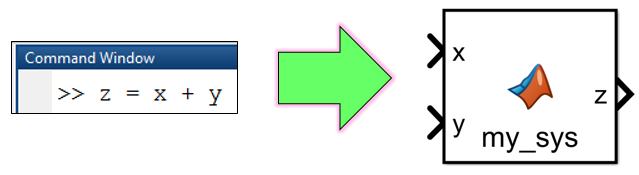

First have a look at the symbols inside each equation:

symvar(  RESULT_TH1  )                          

  and

symvar(  RESULT_TH2  )

Now create the MATLAB function blocks for Simulink:

tf_i_should_create_SL_block = true;
if(true==tf_i_should_create_SL_block)
    MODEL_NAME = 'bh_tmp_model_for_lagr';
    if(4==exist(MODEL_NAME))
        close_system(MODEL_NAME, 0);
        delete(MODEL_NAME);
    end
    new_system(MODEL_NAME)
    open_system(MODEL_NAME)   
    
    % define the INPUT variable order - this is optional
    INPUT_VAR_ORDER = { 'I1G_s', 'I2G_s', ...
                        'L1X_s', 'L2X_s', 'g_s', 'm1_s', 'm2_s', ...
                        'TH1D_s', 'TH1_s', ...
                        'TH2D_s', 'TH2_s', ...
                        'Q1_s', 'Q2_s'};     
                    
    % Put BOTH equations into one block 
    matlabFunctionBlock( [MODEL_NAME,'/THE_THETA_SYS_DD'], RESULT_TH1, RESULT_TH2, ...
                         'Optimize', false, ...
                         'Vars',     INPUT_VAR_ORDER, ...
                         'Outputs', {'theta1_DD', 'theta2_DD'}   );     
end

So now we have one of these !

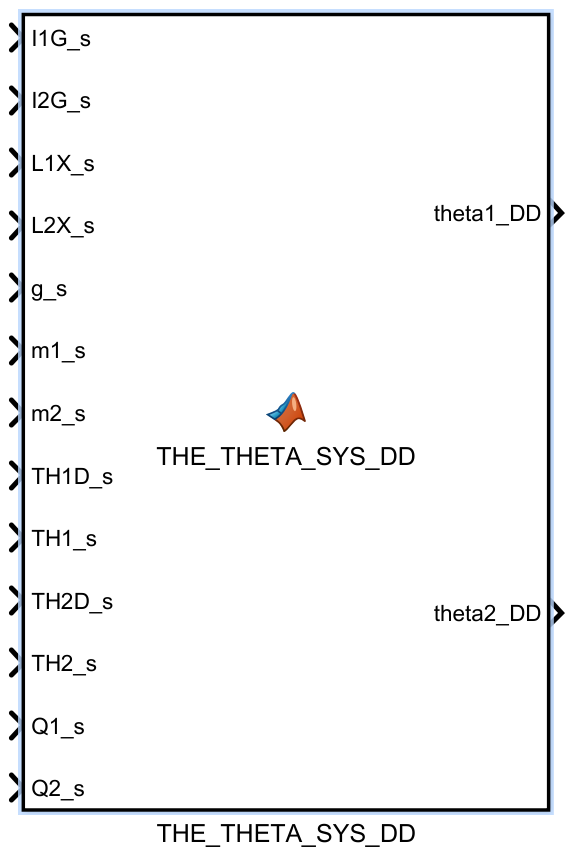

## Implement and solve these equations of motion:

Although we could use MATLAB to numerically solve our system of ODEs, an alternate approach would be to use Simulink.  Our expressions for `theta1_DD` and `theta2_DD`,  have been inserted into the following Simulink model::

-  <`bh_DBL_LAGR_compound_pendulum.slx`> 

Before running the Simulink model, run the script called <`bh_parameters_for_DOUBLE_compound_pendulum.mlx`> to load parameters (eg: inertias, initial conditions, etc) into the MATLAB workspace.  In addition to implementing our hand derived equations of motion, we have also created a Simscape Multibody of the same 2 link manipulator.  We compare the results of our hand derivation to the Simscape model.